# CSB estiamtion for COVID-19 model: 

# multiple estimations to test algorithm

**Load the real data: **Amazonas, Colombia

load('Amazonas.mat');

ydata = ydata(:, 10:end)';
ydata = [ydata(:,3), ydata(:,2), ydata(:,1)];

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

**Create the model as a table for GSUA-CSB toolbox implementation**

Define the model as a symbolic structure

syms S(t) I(t) R(t) D(t) A(t) E(t) Q(t) C(t)
syms alpha beta delta eta tau epsilon mu gamma k lambda nu z sigma

N = S + C + E + A + I + Q + R + D;

ode1 = diff(S) == -alpha*S - beta*I/N*S - sigma*S*A/N - eta*S;
ode2 = diff(A) ==  -tau*A + epsilon*E;
ode3 = diff(C) == alpha*S - mu*C;
ode4 = diff(E) == -gamma*E + beta*I/N*S + mu*C + eta*S + sigma*S*A/N - epsilon*E;
ode5 = diff(I) == tau*A + gamma*E - delta*I;
ode6 = diff(R) == lambda*Q;
ode7 = diff(Q) == delta*I - lambda*Q - k*Q;
ode8 = diff(D) == k*Q;

odes = [ode1; ode2; ode3; ode4; ode5; ode6; ode7; ode8];
vars = [R D I S A C E Q];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [  ydata(1,1) ydata(1,1);  %R
            ydata(1,2) ydata(1,2);  %D    
            ydata(1,3) ydata(1,3);  %I
            7600 80000;             %S
            0 2000;                 %A
            0 1000;                 %C
            0 2000;                 %E
            0 2000                  %Q
];

Range2 = [  0 2;    %alpha
            0 10;   %beta  
            0 1;    %delta
            0 5;    %epsilon
            0 1;    %eta
            0 1;    %gamma
            0 1;    %k
            0 1;    %lambda
            0 1;    %mu
            0 10;   %sigma    
            0 6;    %tau
]; 

Range = [Range1; Range2];


Finally, use the gsua_dpmat to create the functional table

outs = [1,3];
[T,~] = gsua_dpmat(odes,vars,[0 90],'Model','output',outs,'opt',opts,'Range',Range);
% domain=[0 90 0.01]%add a third column with fixed step size to domain variable
% [T,sol] = gsua_dataprep(odes,vars,domain,'Model','solver','ode4');
T.Row = ["S(0)", "A(0)", "C(0)", "E(0)", "Q(0)",...
    "\alpha", "\beta", "\delta", "\epsilon", "\eta", "\gamma", "k", "\lambda", "\mu", "\sigma",  "\tau"];

Define the nominal curve as the best factor estimation

load('Results/Estimations/Deepest_Amazonas.mat')
T.Nominal = Deep;
gsua_eval(T.Nominal, T, xdata, ydata(:,outs)');

**Perform the once-at-time (OAT) algorithm before CSB estimation**

T_oat = gsua_oatr(T,'titerlimit', 10, 'parallel', true, 'correct', true);

Expansion-reduction Method OAT is being launched
------------------------------------
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
Calculus of S(0) Starting
Calculus of C(0) Starting
Calculus of Q(0) Starting
Calculus of \alpha Starting
Calculus of \beta Starting
Calculus of A(0) Starting
Calculus of E(0) Starting
Calculus of \delta Starting
Range for S(0) Done!
Initial range of S(0)(1)--> 7600  80000
Actual range --> 18426.7147      34602.3077
Range for \alpha Done!
Initial range of \alpha(6)--> 0  2
Actual range --> 0.0062015     0.17427
Calculus of \epsilon Starting
Range for \epsilon Done!
Initial range of \epsilon(9)--> 0  5
Actual range --> 0.12449      1.7808
Calculus of \mu Starting
Range for \mu Done!
Initial range of \mu(14)--> 0  1
Actual range --> 0.016465    0.084005
Range for \beta Done!
Initial range of \beta(7)--> 0  10
Actual range --> 0.50953      2.4291
Activating intern_counter for Q(0)
Activat

gsua_save(T_oat, 'T_oatr')

**1. CSB estimation: protecting the nominal value **

N = 5000;
Experiments = 100;
reps = 200;
Up = zeros(16, Experiments);
Low = zeros(16, Experiments);
In = zeros(1, Experiments);

parfor i = 1 : Experiments
    [ParU, ~, ~, ~,sup] = gsua_csb(T_oat, N, 'reps', reps, 'protect', true)
    Low(:, i) = ParU.Range(:, 1);
    Up(:, i) = ParU.Range(:, 2);
    In(i) = max(sup);
    Iters(i) = find(sup == max(sup))
end

save("Results/CSB/CSBRangeProtected_skewness_N_5000", "Low", "Up", "In", "Iters")

**1.1. CSB estimation: Uniqueness for protecting nominal value**

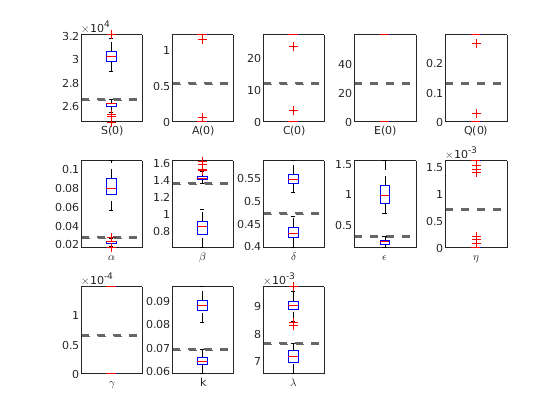

load("Results/CSB/CSBRangeProtected_skewness_N_5000")

Np = 13;
D1 = floor(sqrt(Np));%Number of subplots
D2 = D1+ceil((Np-D1^2)/D1);%Number of subplots

clf
for i=1:Np
    subplot(D1,D2,i)
    boxplot(Low(i,:))
    hold on
    boxplot(Up(i, :),'Labels',T_oat.Properties.RowNames{i})
    set(gca, 'TickLabelInterpreter', 'tex');
    ylim([min(Low(i,:)) max(Up(i,:))])
    yline(Deep(i),'--', 'linewidth',2)
end

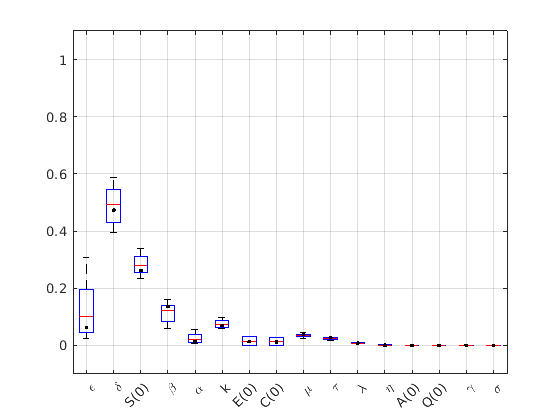

range = T.Range;
NInter = ([Low,Up] - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (Deep - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

boxplot(NInter')
hold on
plot(1:16,Best,'.', 'color', 'k', 'linewidth',3)
ylim([-0.1 1.1])
set(gca,'xticklabel',Names)
set(gca, 'TickLabelInterpreter', 'tex');
grid on

Estimate the uniqueness index

unity(Up,Low,T_oat.Range)

ans = 0.9056

**1.2. Plot the histograms for upper and lower CSB intervals estimated**

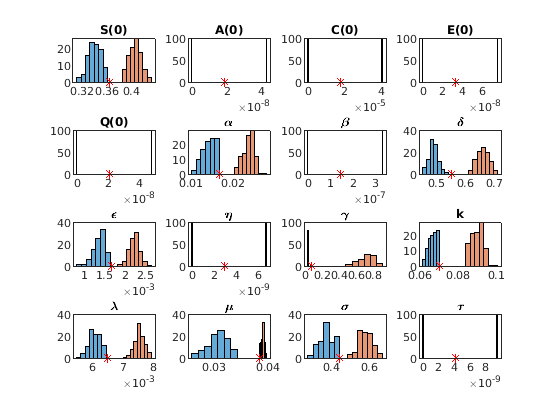

range = T.Range;
LowN = (Low - range(:,1))./(range(:,2)-range(:,1));
UpN = (Up - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (Deep - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

LowN = LowN(idx,:);
UpN = UpN(idx,:);

for i = 1:16
    subplot(4,4,i)
    histogram(LowN(i,:), 'BinLimits', [min(LowN(i,:)), max(LowN(i,:))])
    hold on
    histogram(UpN(i,:), 'BinLimits', [min(UpN(i,:)), max(UpN(i,:))])
    plot(Best(i), 0, 'r.','MarkerSize',16)
    title(Names(i))
end

**2. CSB estimation: without protecting the nominal value **

N = 5000;
Experiments = 100;
reps = 200;
Up = zeros(16, Experiments);
Low = zeros(16, Experiments);
In = zeros(1, Experiments);

parfor i = 1 : Experiments
    [ParU, ~, ~, ~,sup] = gsua_csb(T_oat, N, 'reps', reps, 'protect', false)
    Low(:, i) = ParU.Range(:, 1);
    Up(:, i) = ParU.Range(:, 2);
    In(i) = max(sup);
    Iters(i) = find(sup == max(sup))
end

save("Results/CSB/CSBRangeUnProtected_skewness_N_5000", "Low","Up", "In", "Iters")

**2.1. CSB estimation: Uniqueness without protecting the nominal value**

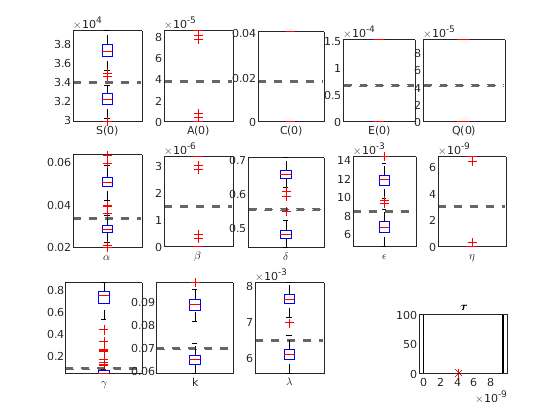

load("Results/CSB/CSBRangeUnProtected_skewness_N_5000.mat" )

Np = 13;
D1 = floor(sqrt(Np));%Number of subplots
D2 = D1+ceil((Np-D1^2)/D1);%Number of subplots

for i=1:Np
    subplot(D1,D2,i)
    boxplot(Low(i,:))
    hold on
    boxplot(Up(i, :),'Labels',T_oat.Properties.RowNames{i})
    set(gca, 'TickLabelInterpreter', 'tex');
    ylim([min(Low(i,:)) max(Up(i,:))])
    yline(BestParams(i),'--', 'linewidth',2)
end

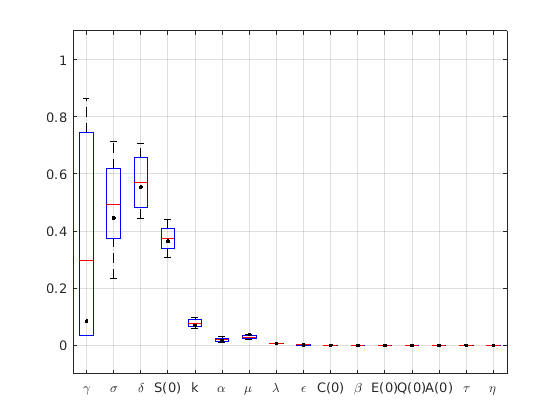

range = T.Range;
NInter = ([Low,Up] - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (Deep - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

boxplot(NInter')
hold on
plot(1:16,Deep,'.', 'color', 'k', 'linewidth',3)
ylim([-0.1 1.1])
set(gca,'xticklabel',Names)
set(gca, 'TickLabelInterpreter', 'tex');
grid on

Estimate the uniqueness index

res = unity(Up,Low,T_oat.Range)

res = 0.8976

#### **Plot the histograms for upper and lower CSB intervals estimated**

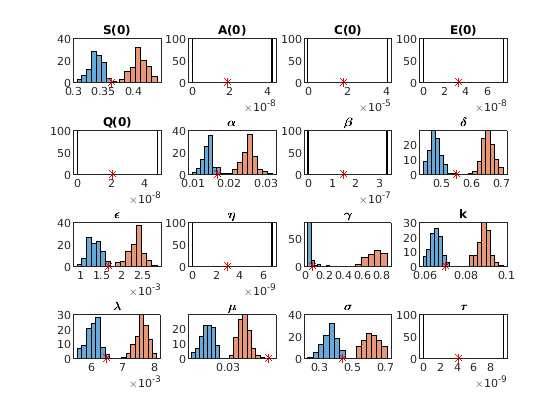

range = T.Range;
LowN = (Low - range(:,1))./(range(:,2)-range(:,1));
UpN = (Up - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (Deep' - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

LowN = LowN(idx,:);
UpN = UpN(idx,:);

for i = 1:16
    subplot(4,4,i)
    histogram(LowN(i,:),'BinLimits',[min(LowN(i,:)), max(LowN(i,:))])
    hold on
    histogram(UpN(i,:),'BinLimits',[min(UpN(i,:)), max(UpN(i,:))])
    plot(Best(i), 0, 'r.','MarkerSize',16)
    title(Names(i))
end


% boxplot(NInter')
% hold on
% plot(1:16,Best,'.', 'color', 'k', 'linewidth',3)
% ylim([-0.1 1.1])
% set(gca,'xticklabel',Names)
% set(gca, 'TickLabelInterpreter', 'tex');
% grid on

**4. SA: median of multiple protected CSB estimations**

load("Results/CSB/CSBRangeProtected_skewness_N_5000.mat")
MedianUp = median(Up');
MedianLow = median(Low');
T.Range(:,1) = MedianLow;
T.Range(:,2) = MedianUp;

N = 10000; 
M = gsua_dmatrix(T, N, 'Method', 'Sobol');
T_sa = gsua_sa(M, T);

Current outputs:1  3
Progress: 6%
Estimated processing time (h:m:s): 0:1:23
Remaining time (h:m:s): 0:1:18
Elapsed time (h:m:s): 0:0:4
Estimated stop time (h:m:s): 16:4:40
Number of simulations: 90000
Progress: 12%
Estimated processing time (h:m:s): 0:1:37
Remaining time (h:m:s): 0:1:27
Elapsed time (h:m:s): 0:0:10
Estimated stop time (h:m:s): 16:4:55
Number of simulations: 90000
Finding the deepest curve...
Progress: 17%
Estimated processing time (h:m:s): 0:3:31
Remaining time (h:m:s): 0:2:55
Elapsed time (h:m:s): 0:0:35
Estimated stop time (h:m:s): 16:6:48
Number of simulations: 90000
Progress: 23%
Estimated processing time (h:m:s): 0:2:59
Remaining time (h:m:s): 0:2:19
Elapsed time (h:m:s): 0:0:39
Estimated stop time (h:m:s): 16:6:17
Number of simulations: 90000
Progress: 28%
Estimated processing time (h:m:s): 0:2:41
Remaining time (h:m:s): 0:1:56
Elapsed time (h:m:s): 0:0:44
Estimated stop time (h:m:s): 16:5:58
Number of simulations: 90000
Progress: 34%
Estimated processing time (h

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 0.9579

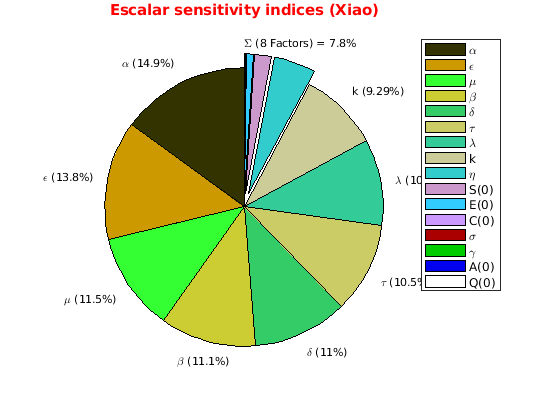

clf
gsua_plot('Pie',T_sa,T_sa.STi)

# **Performance with multiple number of samples (160, 500, 1000, 2000)**

N = [150, 500, 1000, 2000];
Experiments = 100;
reps = 200;

for j = 1 : length(N)
    Up = zeros(16, Experiments);
    Low = zeros(16, Experiments);
    In = zeros(1, Experiments);
    err = zeros(1, Experiments);
    Iters = zeros(1, Experiments);
    parfor i = 1 : Experiments
        [ParU, ~, ~, ~,sup, E] = gsua_csb(T_oat, N(j), 'reps', reps, 'protect', true);
        Low(:, i) = ParU.Range(:, 1);
        Up(:, i) = ParU.Range(:, 2);
        In(i) = max(sup);
        Iters(i) = find(sup == max(sup), 1, 'last' );
        err(i) = max(abs(E));
    end
    save("Results/CSB/CSBRangeProtected_skewness_N_" + num2str(N(j)), "Low","Up", "In", "Iters","err")
end